# Getting the DTFT from data

## Introduction

In this tutorial you will learn how to get the Discrete Time Fourier Transform (DTFT) of a time series with $N$ elements,$x[0], x[1], ..., x[N-1]$.

## Tutorial

First of all, add mVARbox to path, and set the tutorial parameters.

setmVARboxPath

mVARbox path has been added to MATLAB path



clear
clc
close all


%%% Parameters
delta_t     = 0.05;             % sampling time [seconds]
f_max       = 1/(2*delta_t);    % maximum frequency
N_f         = 100;              % number of elements of the frequency vector
k           = 3;                % to select k-th time series


%%% Plot parameters
font_size   = 18;
figure_position = [0 0 1000 400];

Define three time series. Initialise a data object with the fields required by function `get_DTFT_data`.

x1          = [0 1 zeros(1,18)]';       % A single one
x2          = ones(1,20)';              % All ones
x3          = sin(2*pi*6*(1:20)/20)';   % A sin(x) function with frequency 6 Hz

data = initialise_data('ind_var','t',...
                       'delta_x',delta_t,...
                       'y_values',[x1 x2 x3]);

Define the frequency vector where the DTFT will be evaluated.

% Frequency vector
f_vector    = transpose(linspace(-f_max,f_max,N_f));

Initialise a DTFT object with the fields required by function `get_DTFT_data`.

DTFT = initialise_DTFT('x_values', f_vector);

Compute the DTFT of the $k$-th time series.

DTFT = get_DTFT_data(data ,DTFT ,k);

The DTFT is complex-valued. Plot real and imaginary parts.

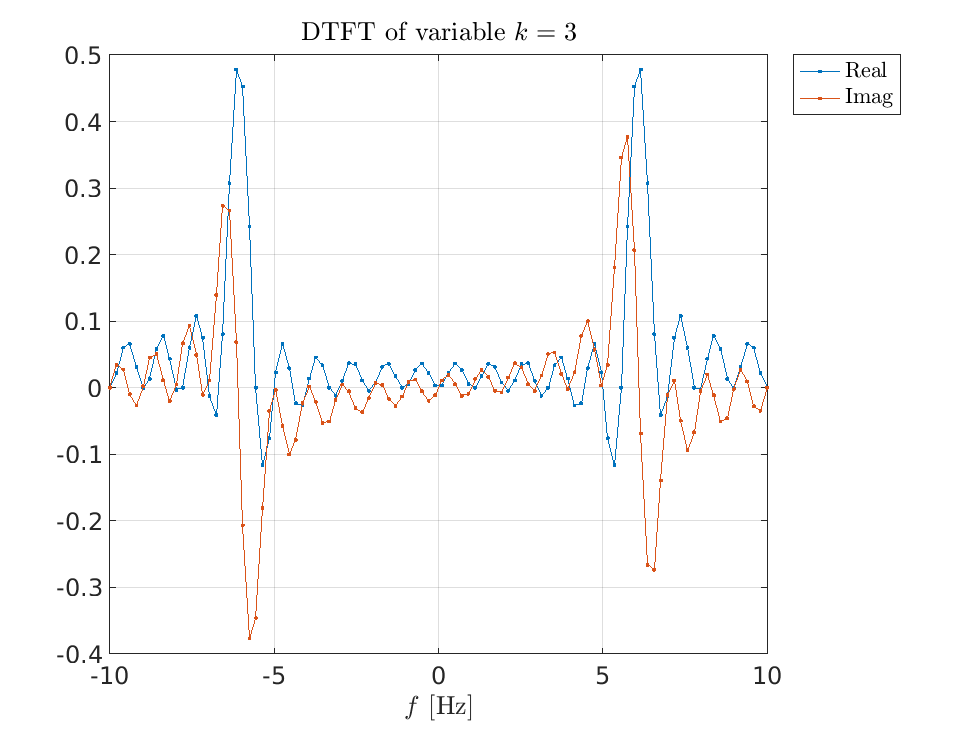

figure

x = DTFT.x_values;
y = real(DTFT.y_values);
plot(x,y,'.-')

hold on

x = DTFT.x_values;
y = imag(DTFT.y_values);
plot(x,y,'.-')

grid on

xlabel('$f$ [Hz]','Interpreter','latex')
legend({'Real','Imag'},'Interpreter','latex','Location','bestoutside')

set(gca,'fontsize',font_size)

title(sprintf('DTFT of variable $k=%d$',k),'Interpreter','latex')

Compute the DTFT for all the time series, by selecting $k=0$.

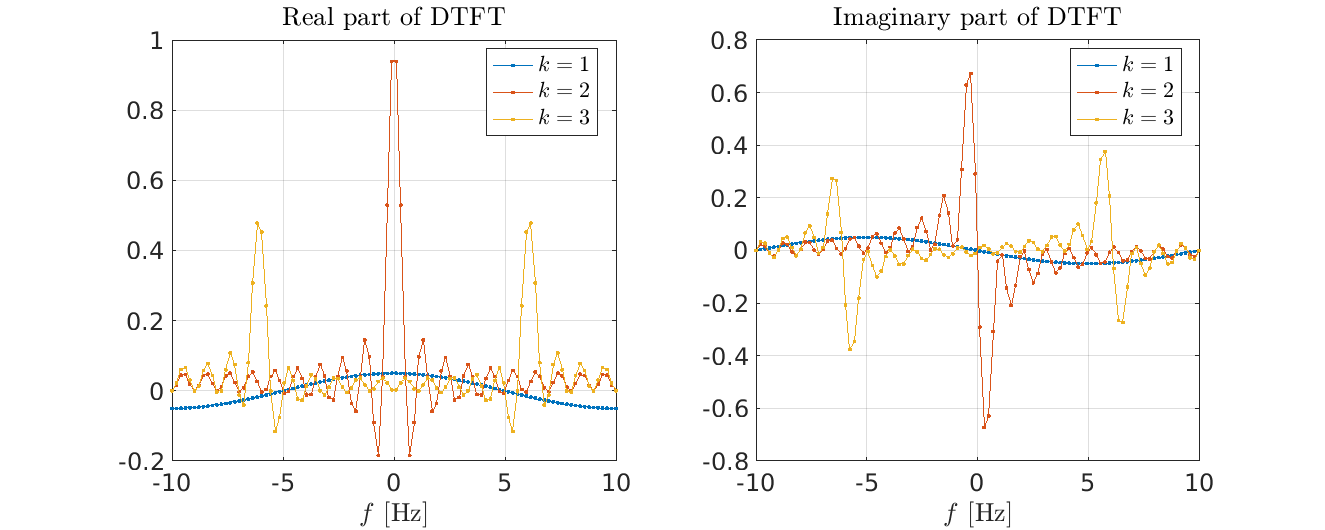

k = 0;

DTFT = get_DTFT_data(data, DTFT, k);

figure

subplot(1,2,1)
x = DTFT.x_values;
y = real(DTFT.y_values);
plot(x,y,'.-')
grid on
legend({'$k=1$','$k=2$','$k=3$'},...
        'Interpreter','latex',...
        'Location','best')
title('Real part of DTFT','Interpreter','latex')
xlabel('$f$ [Hz]','Interpreter','latex')
set(gca,'fontsize',font_size)

subplot(1,2,2)
x = DTFT.x_values;
y = imag(DTFT.y_values);
plot(x,y,'.-')
grid on
legend({'$k=1$','$k=2$','$k=3$'},...
        'Interpreter','latex',...
        'Location','best')
title('Imaginary part of DTFT','Interpreter','latex')
xlabel('$f$ [Hz]','Interpreter','latex')
set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

## Remarks

- Note that the DTFT is a continuous function of the frequency. The well-known FFT (Fast Fourier Transform) is an efficient algorithm to compute the DTFT in a certain number of equidistant frequency values. The algorithm  implemented in mVARbox is not as fast as the FFT, but the frequency vector may be defined at will, which may be handy for example if the DTFT is going to be represented in x-log scale, or if refinement is required within a specific range of frequencies.

- Note that, due to its definition, the real part of the DTFT is an even function, while the imaginary part is an odd function (this applies only for real time series).

- The DTFT is, due to its definition, a smooth function. The seemingly spiking behaviour in a plot can be avoided just by increasing the number of points in the frequency vector (`N_f`).

- Note that the DTFT is periodic, with range $[ -f_{max} , f_{max} ]$. You can check it just by changing `f_vector` beyond this range.